%robot parameters
r = 1.5;
L=3;
R=3.5;

params = [r, L, R];

%variables
x0 = [1, -0.1, 0];
xf = [0, 0.75, 90];
t = linspace(0,2,5)

t =          0    0.5000    1.0000    1.5000    2.0000


n = length(t);
T = t(end);

%xplan
x = x_plan(x0,xf,t);

%inv kin
q = inv_kin(x, t, params);

%drawing
x1 = x0(1); x2 = x0(1)+r*cos(x0(3)); x3 = x0(1)+r*cos(x0(3)+deg2rad(60));

Unrecognized function or variable 'x0'.

y1 = x0(2); y2 = x0(2)+r*sin(x0(3)); y3 = x0(2)+r*sin(x0(3)+deg2rad(60));


figure
hold on;
patch([x1 x2 x3], [y1 y2 y3], 'green', 'edgecolor', 'red')
plot([x1 R*cos(q(3,1)) ], [y1 R*sin(q(3,1)) ], 'blue', 'linewidth', 2);
plot([R*cos(q(5,1)) x1+r*cos(x0(3))],[R*sin(q(5,1)) y1+r*sin(x0(3))], 'blue', 'linewidth', 2);
plot([R*cos(q(1,1)) x1+r*cos(pi/3+x0(3))],[R*sin(q(1,1)) y1+r*sin(pi/3+x0(3))], 'blue', 'linewidth', 2);

viscircles([0,0],R);
grid on
axis equal

xlim([-4.67 4.54])
ylim([-3.65 3.61])

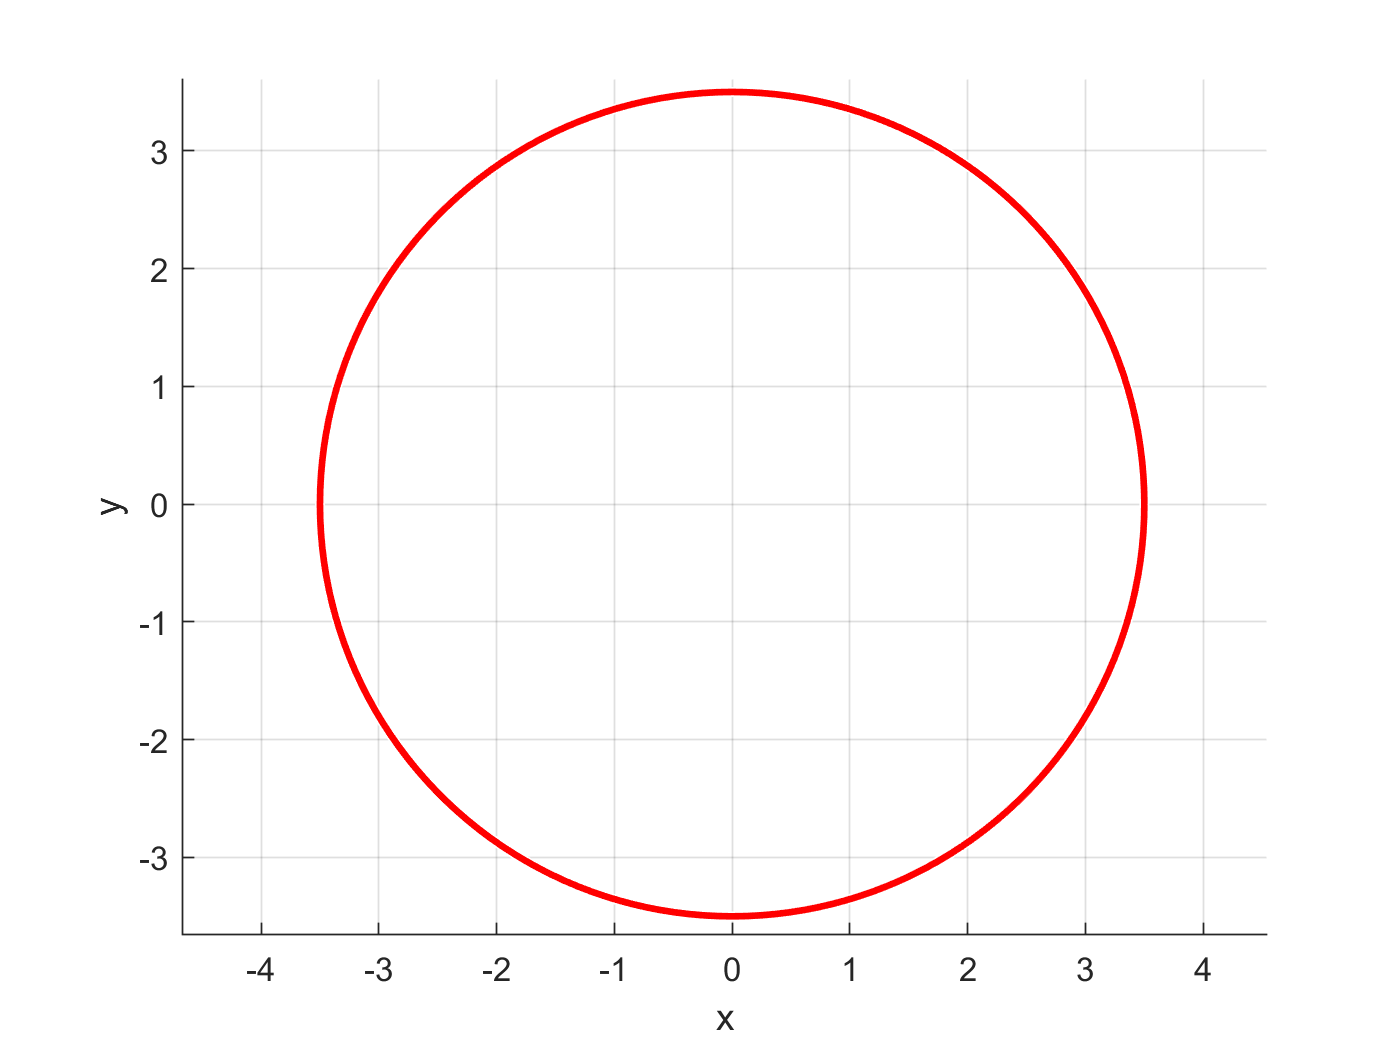

figure
for i=1:n
    x1 = x(1,i); x2 = x(1,i)+r*cos(x(3,i)); x3 = x(1,i)+r*cos(x(3,i)+deg2rad(60));
    y1 = x(2,i); y2 = x(2,i)+r*sin(x(3,i)); y3 = x(2,i)+r*sin(x(3,i)+deg2rad(60));
    hold on;
    p1 = patch([x1 x2 x3], [y1 y2 y3], 'green', 'edgecolor', 'red');
    p2 = plot([x1 R*cos(q(3,i)) ], [y1 R*sin(q(3,i)) ], 'blue', 'linewidth', 2);
    p3 = plot([R*cos(q(5,i)) x1+r*cos(x(3,i))],[R*sin(q(5,i)) y1+r*sin(x(3,i))], 'blue', 'linewidth', 2);
    p4 = plot([R*cos(q(1,i)) x1+r*cos(pi/3+x(3,i))],[R*sin(q(1,i)) y1+r*sin(pi/3+x(3,i))], 'blue', 'linewidth', 2);
    hold off;
    viscircles([0,0],R);
    grid on
    axis equal
    pause(T/n);
    xlim([-4.67 4.54])
    ylim([-3.65 3.61])
    grid on
    xlabel('x')
    ylabel('y')
    title = ['visualization of trajectory'];
    a(i) = norm([x1  y1] - [R*cos(q(3,i)) R*sin(q(3,i)) ]);
    b(i) = norm([R*cos(q(5,i)) R*sin(q(5,i))] - [x1+r*cos(x0(3)) y1+r*sin(x(3,i))]);
    c(i) = norm([R*cos(q(1,i)) R*sin(q(1,i))] - [x1+r*cos(pi/3+x(3,i)) y1+r*sin(pi/3+x(3,i))]);
    delete(p1);delete(p2);delete(p3);delete(p4);
end
hold off;

a

a =     3.0000    3.0000    3.0000    3.0000    3.0000


b

b =     3.0000    3.5622    4.0363    4.3125    4.3258


c

c =     3.0000    3.4989    3.9839    4.4198    4.7716


q

q =    -0.4210   -0.2647   -0.1001    0.0639    0.2202
   -0.4210   -0.2647   -0.1001    0.0639    0.2202
    0.8207   -0.6173    0.0482    0.6156    0.8128
    0.8207   -0.6173    0.0482    0.6156    2.3288
   11.5296   -0.9601   -0.8544   -0.7155   -0.5431
   11.5296   -0.9601   -0.8544   -0.7155   -0.5431
